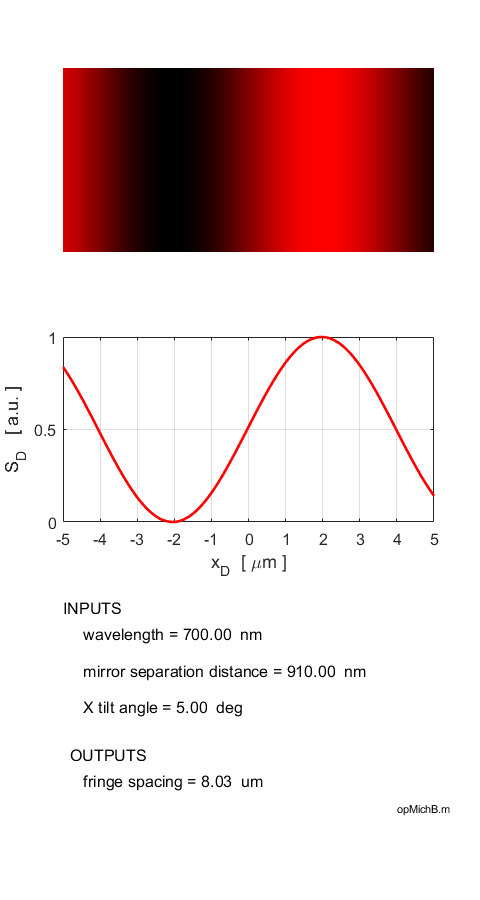

% op_michBLE.m

% Michelson Interferometer
%   Plane Wave illumination of mirrors
%   Mirror M1I fixed precisely aligned at right angles to the beam
%   Mirror M2 movable at tilt angle thetaX to beam
%   Intensity is displayed on Detectoro screen due to the
%     interference from the reflections from the two mirrors

% DOING PHYSICS WITH MATLAB: 
%   http://www.physics.usyd.edu.au/teach_res/mp/mphome.htm
% Documentation
%   http://www.physics.usyd.edu.au/teach_res/mo/doc/op_michelson.htm
% Download Scripts
%   http://www.physics.usyd.edu.au/teach_res/mp/mscripts/


% Ian Cooper  ian.cooper@sydney.edu.au
% School of Physics, University of Sydney
% 190723   Matlab 2018b

clear
close all
clc

   
% SETUP  ==============================================================

% Input wavelength [nm] >>>
 wL= 700;
  
% Input Mirror separation distance >>>
  dM = 1.3;
  
% Input X tilt angle  [deg]  >>>
 thetaX = 5;
 
% CALCULATIONS ========================================================  
wL = wL * 1e-9;
dM = dM * wL ;
  
% Detector screen dimensions L [m]
  L = 5e-6;
% Number of grid points
  nD = 501;

% Propagation constant  [1/m]
  k = 2*pi/wL;

% Detector screen
  xD = linspace(-L,L,nD);
  yD = xD;
  zD = 1;

% fringe spacing  
  dF = 1*wL/sind(thetaX);
  
% Electric field at Detector Screen
  E1   = zeros(nD,nD);
  E2   = E1;
   
  for cx = 1: nD
  E1(:,cx) = exp(1i*k*(zD + 2*dM) + 1i*pi);
  E2(:,cx) = exp(1i*(k*zD*cosd(thetaX) + k*xD(cx)*sind(thetaX)));
  end
  
 Etot = E1 + E2;
 
% Detector screen intensity 
 SD = Etot .* conj(Etot);
 SD = SD./max(max(SD));
  
  
% GRAPHICS =======================================================
 
figure(1)
   pos = [0.1 0.2 0.25 0.75];
   set(gcf,'Units','normalized')
   set(gcf,'Position',pos)
   set(gcf,'color','w')
   
subplot(3,1,1)
   xP = 1e6.*xD; yP = 1e6.*yD;
   pcolor(xP,yP,SD)
   col = ColorCode(wL);
   colorMap = [linspace(0,col(1),256)',linspace(0,col(2),256)',linspace(0,col(3),256)' ];
   colormap(colorMap);  
   shading flat
   xlim([-5,5])
   set(gca,'fontsize',12)
   axis off
 
subplot(3,1,2)
  col = ColorCode(wL);
  plot(xD.*1e6,SD(1,:),'color',col','linewidth',2)
  xlim([-5,5])
  set(gca,'xtick',-5:5)
  grid on
  set(gca,'fontsize',12)
  xlabel('x_D  [ \mum ]')
  ylabel('S_D   [ a.u. ]')
  
  
subplot(3,1,3) 
     xlim([0 100])
     ylim([0 100])
     h = 100; dh = -20;
     text(0,h,'INPUTS','fontsize',12)
     h = h+dh;
     txt = sprintf('   wavelength = %3.2f  nm  \n',wL*1e9);
     text(2,h,txt,'fontsize',12)
     h = h+dh;
     txt = sprintf('   mirror separation distance = %3.2f  nm  \n',dM*1e9);
     text(2,h,txt,'fontsize',12)
     h = h+dh;
     txt = sprintf('   X tilt angle = %3.2f  deg  \n',thetaX);
     text(2,h,txt,'fontsize',12)
      h = h+dh;
     txt = sprintf('OUTPUTS');
     text(2,h,txt,'fontsize',12)
     h = h+dh;
     txt = sprintf('   fringe spacing = %3.2f  um  \n',dF*1e6)   ;
     text(2,h,txt,'fontsize',12)
     text(90,-10,'opMichB.m','fontsize',8)
     axis off